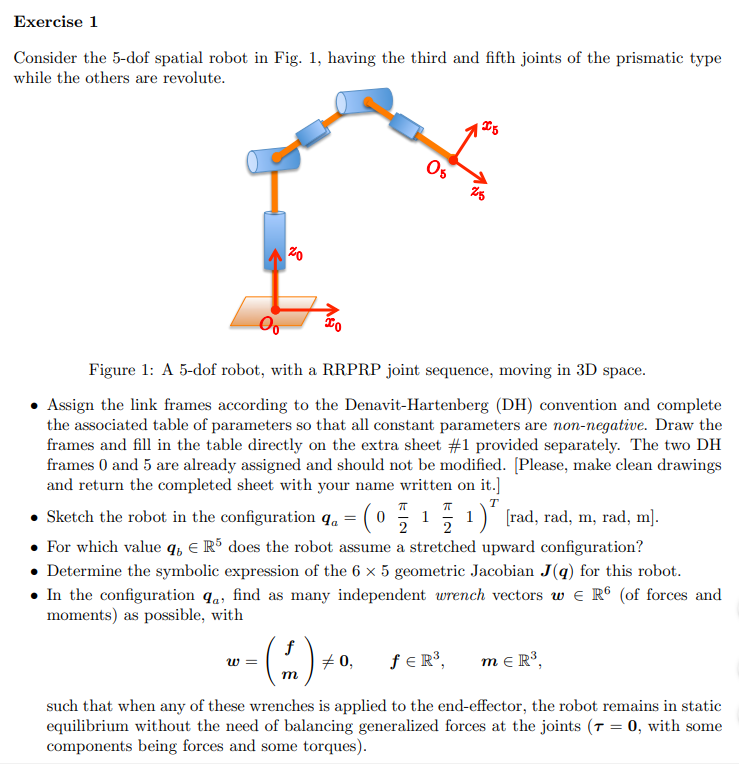

clear all, close all, clc
syms A B C D q1 q2
Njoints=5;
q=sym('q',[Njoints,1]);

d1_=1;
d2_=1;
syms alpha beta gamma

a1=A

$$a1 = A$$

a2=6

a2 = 6

dhTable=[pi/2,0,d1_,q(1);
         pi/2,0,0,q(2);
         pi/2,0,q(3),pi;
         pi/2,0,0,q(4);
         0,0,q(5),0
         ];
links = [
    Revolute('alpha', pi/2, 'a', 0 ,'d', d1_);
    Revolute('alpha',  pi/2, 'a', 0,'d', 0);
    Prismatic('qlim', [0 5],'alpha',pi/2,'theta',pi);
    Revolute('alpha',  pi/2, 'a', 0,'d', 0);
    Prismatic('qlim', [0 5],'alpha',0,'theta',0);
    ]

 
links = 
Revolute(std):  theta=q1   d=1           a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q2   d=0           a=0           alpha=1.571       offset=0          
Prismatic(std): theta=3.142         d=q3 a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q4   d=0           a=0           alpha=1.571       offset=0          
Prismatic(std): theta=0             d=q5 a=0           alpha=0           offset=0          


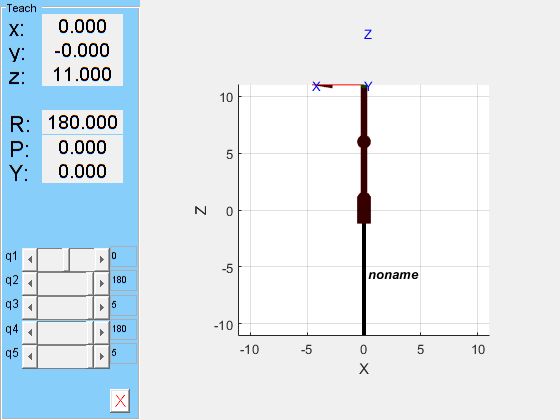

c600 = SerialLink(links);
c600.teach([0 ,pi,5,pi,5],'view','x')

[T_total T_Partial,RTotal,RPartial,PTotal, PPartial] = getTransformationMatrix(dhTable, 'alpha');

PTotal

$$PTotal = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(q_{5}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(q_{5}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ q_{5}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)+1 \end{array}\right)$$

JL_D=simplify(jacobian(PTotal,q))

$$JL\_D = \begin{array}{l} \left(\begin{array}{ccccc} \sin\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{1} & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -q_{5}\,\cos\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right)\,\sigma_{2} & -\sin\left(q_{1}\right)\,\sigma_{1} & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -q_{5}\,\cos\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right)\\ 0 & q_{3}\,\sin\left(q_{2}\right)-\sigma_{3} & -\cos\left(q_{2}\right) & -\sigma_{3} & \cos\left(q_{2}+q_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q_{5}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ \sigma_{2}=\sigma_{3}-q_{3}\,\sin\left(q_{2}\right)\\ \sigma_{3}=q_{5}\,\sin\left(q_{2}+q_{4}\right) \end{array}$$


sigma = [0,0,1,0,1];
[Jp, Jo,Jps, Jos] = getJacobian(dhTable, sigma, 'alpha');

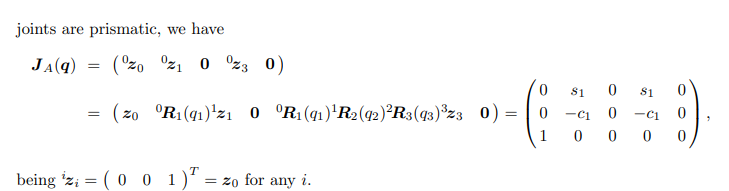

J=[Jp;Jo]

$$J = \begin{array}{l} \left(\begin{array}{ccccc} \sin\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{1} & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -q_{5}\,\cos\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right)\,\sigma_{2} & -\sin\left(q_{1}\right)\,\sigma_{1} & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -q_{5}\,\cos\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right)\\ 0 & q_{3}\,\sin\left(q_{2}\right)-\sigma_{3} & -\cos\left(q_{2}\right) & -\sigma_{3} & \cos\left(q_{2}+q_{4}\right)\\ 0 & \sin\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ 0 & -\cos\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q_{5}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ \sigma_{2}=\sigma_{3}-q_{3}\,\sin\left(q_{2}\right)\\ \sigma_{3}=q_{5}\,\sin\left(q_{2}+q_{4}\right) \end{array}$$

sincos =getShortNotation_SinCos(Njoints);
toShortNotation(J,sincos)

$$ans = \begin{array}{l} \left(\begin{array}{ccccc} -s_{1}\,\sigma_{1} & c_{1}\,\sigma_{2} & c_{1}\,s_{2} & -c_{1}\,c_{2,4}\,q_{5} & -c_{1}\,s_{2,4}\\ c_{1}\,\sigma_{1} & s_{1}\,\sigma_{2} & s_{1}\,s_{2} & -c_{2,4}\,q_{5}\,s_{1} & -s_{1}\,s_{2,4}\\ 0 & \sigma_{1} & -c_{2} & -q_{5}\,s_{2,4} & c_{2,4}\\ 0 & s_{1} & 0 & s_{1} & 0\\ 0 & -c_{1} & 0 & -c_{1} & 0\\ 1 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q_{3}\,s_{2}-q_{5}\,s_{2,4}\\ \sigma_{2}=c_{2}\,q_{3}-c_{2,4}\,q_{5} \end{array}$$

q_=[0,pi/2,1,pi/2,1]';
J_=simplify(vpa(subs(J,q,q_)))

$$J\_ = \left(\begin{array}{ccccc} 0 & 1.0 & 1.0 & 1.0 & 0\\ 1.0 & 0 & 0 & 0 & 0\\ 0 & 1.0 & 0 & 0 & -1.0\\ 0 & 0 & 0 & 0 & 0\\ 0 & -1.0 & 0 & -1.0 & 0\\ 1.0 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_'

$$ans = \left(\begin{array}{cccccc} 0 & 1.0 & 0 & 0 & 0 & 1.0\\ 1.0 & 0 & 1.0 & 0 & -1.0 & 0\\ 1.0 & 0 & 0 & 0 & 0 & 0\\ 1.0 & 0 & 0 & 0 & -1.0 & 0\\ 0 & 0 & -1.0 & 0 & 0 & 0 \end{array}\right)$$

rank(J_')

ans = 4

null(J_')

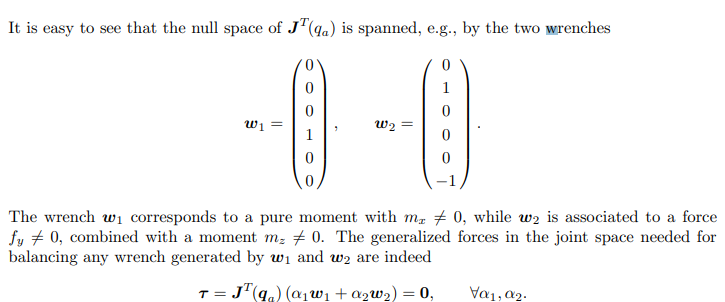

w1=[0 0 0 1 0 0]';
w2=[0 1 0 0 0 -1]';
alpha=sym('alpha',[1 2])

$$alpha = \left(\begin{array}{cc} \alpha_{1} & \alpha_{2} \end{array}\right)$$

tao=J_'*(alpha(1)*w1+alpha(2)*w2)

$$tao = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$